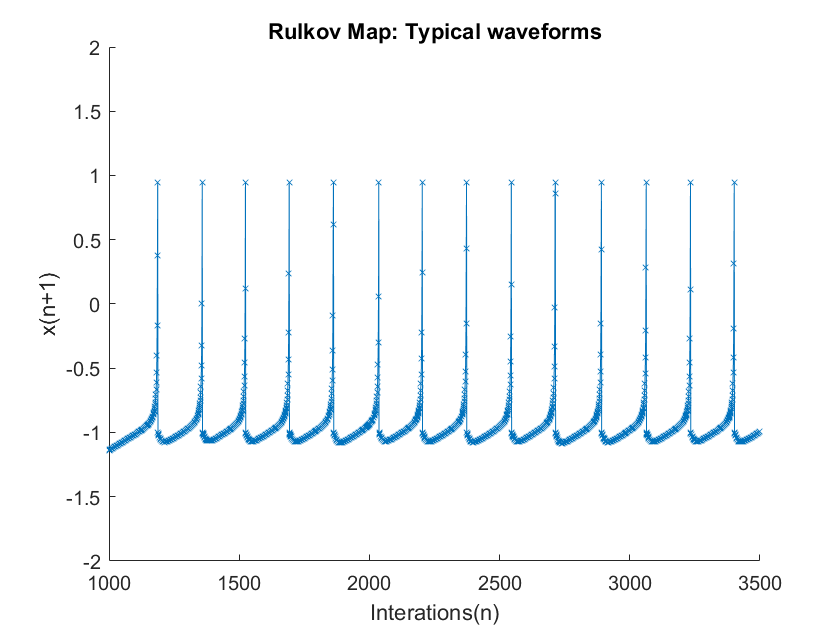

x(1)=-20;
y(1)=-3.93;
a=3.9;
b=0.001;
c=0.04;
% and now we begin the iteration (10000 iterations):
for n=1:10000
    y(n+1)=y(n) - b*(x(n)-c +1);
        if x(n)<=0
        x(n+1) = (a/(1-x(n)))+y(n);
        elseif x(n)>0 && x(n)<a+y(n)
        x(n+1) = a+y(n);
        else
        x(n+1) = -1;
        end
end
hold on
plot((1:9999),x(1:9999),'-x','MarkerSize',4)
title('Rulkov Map: Typical waveforms')
xlabel('Interations(n)') 
ylabel('x(n+1)') 
hold off

xlim([1000 3500])
ylim([-2 2])

numel(x)

ans = 10001